%% Part 2: SETAR(2;1;1) with regsmooth1D smoother
rng default

% --- Model parameters ---
phi10 = 1;   phi11 = 0.6;    % Regime 1
phi20 = 0.5; phi21 = -0.4;   % Regime 2
r     = 0;                   % threshold
sigma = 1.0;                 % noise std

% --- Simulate with burn-in ---
N = 1000; B = 200; T = N + B;
e = sigma * randn(T,1);
X = zeros(T,1); 
X(1) = 0;

for t = 2:T
    if X(t-1) <= r
        X(t) = phi10 + phi11 * X(t-1) + e(t);
    else
        X(t) = phi20 + phi21 * X(t-1) + e(t);
    end
end

X = X(B+1:end);
xt = X(1:end-1);
yt = X(2:end);

% --- Theoretical conditional mean ---
M_true = @(x) (phi10 + phi11*x) .* (x <= r) + (phi20 + phi21*x) .* (x > r);

% LaTeX model string
fprintf(['$$\n' ...
    'E[X_{t+1} \\mid X_t = x] =\n' ...
    '\\begin{cases}\n' ...
    '%.2f + %.2f x, & x \\leq %.2f, \\\\\n' ...
    '%.2f + %.2f x, & x > %.2f\n' ...
    '\\end{cases}\n' ...
    '$$\n'], phi10,phi11,r,phi20,phi21,r);

$$
E[X_{t+1} \mid X_t = x] =
\begin{cases}
1.00 + 0.60 x, & x \leq 0.00, \\
0.50 + -0.40 x, & x > 0.00
\end{cases}
$$


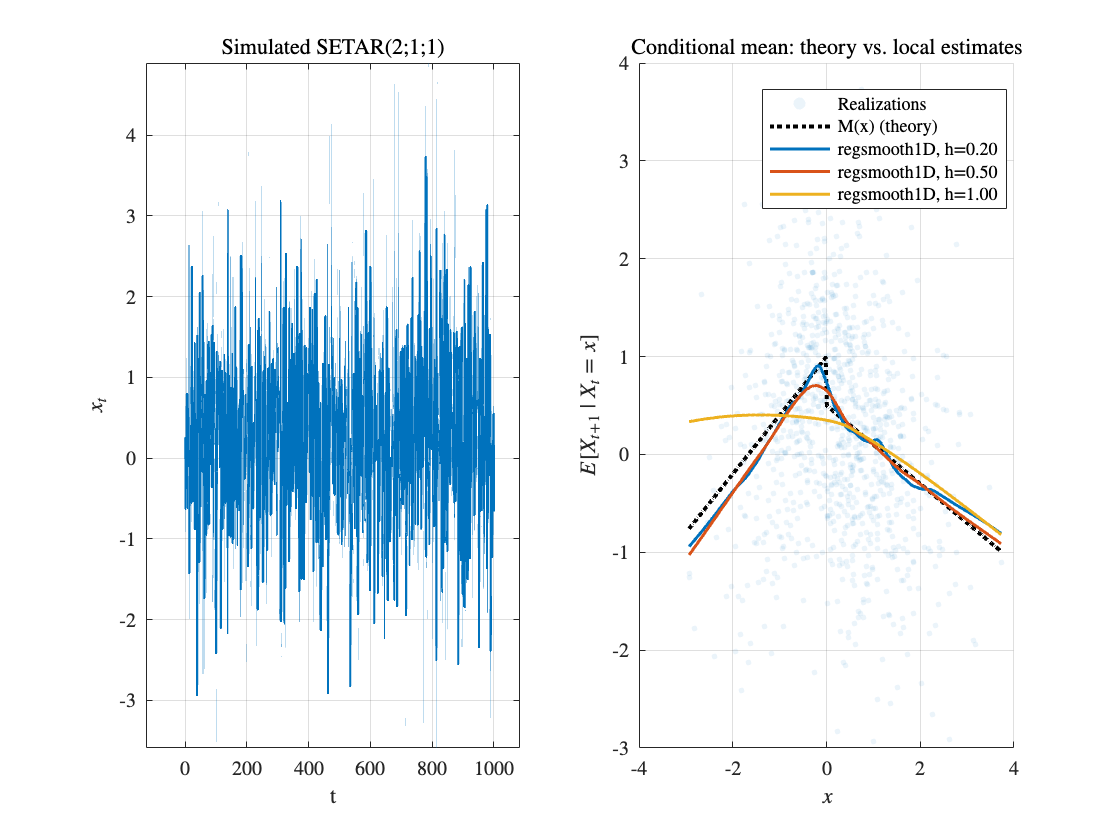


% --- Use regsmooth1D for local regression estimates ---
points = 250;   % resolution for the x-grid
order  = 1;     % local polynomial order (linear)
bandwidths = [0.2, 0.5, 1.0];   % bandwidth as fraction of sample size (h in regsmooth1D)

Mhat = cell(numel(bandwidths),1);
xgrid = [];

for j = 1:numel(bandwidths)
    [xgrid, ytilde] = regsmooth1D([xt, yt], points, order, bandwidths(j));
    Mhat{j} = ytilde(:);
end

% --- Plot results ---
figure('Name','M(x): Theoretical vs Local Regression','Color','w');

subplot(1,2,1);
plot(X, 'LineWidth', 1.2);
xlabel('t'); ylabel('$x_t$', "Interpreter","latex");
title('Simulated SETAR(2;1;1)', "Interpreter","latex"); grid on

subplot(1,2,2); hold on; grid on
scatter(xt, yt, 8, 'filled', ...
    'MarkerFaceAlpha', 0.08, 'MarkerEdgeAlpha', 0.08);

% Theoretical conditional mean (dotted)
plot(xgrid, M_true(xgrid), 'k:', 'LineWidth', 2, 'DisplayName','M(x) (theory)');

% Smoother estimates
cmap = lines(numel(bandwidths));
for j = 1:numel(bandwidths)
    plot(xgrid, Mhat{j}, '-', 'LineWidth', 1.5, ...
        'Color', cmap(j,:), ...
        'DisplayName', sprintf('regsmooth1D, h=%.2f', bandwidths(j)));
end

xlabel('$x$', "Interpreter","latex"); 
ylabel('$E[X_{t+1} \mid X_t=x]$', "Interpreter","latex");
title('Conditional mean: theory vs. local estimates', "Interpreter","latex");
legend('Location','best');
hold off;